clc;
clf;
clear;

# Shaft Design (Steel)

by **Winston Chou**, A17460970

This is a simple circular rotating shaft design problem. The code computes the required diameter of a circular shaft based on user input for material properties, dynamic loading, safety factor, and selected failure criteria.

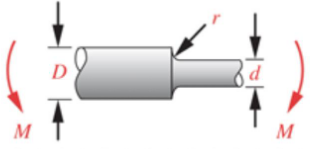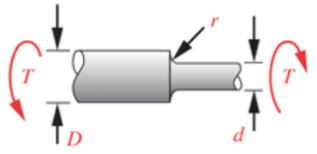

## Input Section

### Material Selection:

% material selection
material_name = "";
unit = "Imperial";
switch unit
    case 'Metric'
        stress_unit = 'MPa';
        length_unit = 'mm';
    case 'Imperial'
        stress_unit = 'ksi';
        length_unit = 'in';
end
Sy = 58;    Sut = 82;
material = struct('name',material_name, ...
                  'unit',unit, ...
                  'yield',Sy, ...
                  'ultimate',Sut, ...
                  'endurance',getEnduranceLimitSteel(Sut,stress_unit), ...
                  'modified_Se',getEnduranceLimitSteel(Sut,stress_unit));

### Loadings:

% loadings
loadings = [1250,1250, ... 
            3750,2250];

### Marin Factors:

% marin factors
surface = "Machined / Cold-drawn";
temperature = struct('value',70,'unit',"Fahrenheit");
reliability = double("99.9");
marin_factors = struct('ka', getSurfaceMarinFactor(Sut, surface, stress_unit), ...
                       'kb', 1.0, ...
                       'kc', 1.0, ...
                       'kd', getTemperatureMarinFactor(temperature.value, temperature.unit), ...
                       'ke', getReliabilityMarinFactor(reliability));

### Design Requirements:

n_safety = 1.5;
D_d = 1.2;
r_d = 0.1;
criteria = "DE-Gerber"; tol = 0.01;
marin_factors.kb = 0.9;

% 1st Iteration
% Compute Initial Se
material.modified_Se = (marin_factors.ka * marin_factors.kb * marin_factors.kc * marin_factors.kd * marin_factors.ke) * material.endurance;
[Kt, Kts] = calculateStressConcentration(D_d,r_d);  % compute Stress Concentration Factors

% Find suitable guess for intial Fatigue Stress Concentration Factors
fillet_range_r_d = [0.1, 0.02];
initial_guess_Kf = [1.7, 2.7];
initial_guess_Kfs = [1.5, 2.2];
Kf = interp1(fillet_range_r_d, initial_guess_Kf, r_d);
Kfs = interp1(fillet_range_r_d, initial_guess_Kfs, r_d);

% Compute 1st Diameter
d_1 = computeDiameter(loadings(1),loadings(2),loadings(3),loadings(4), ...
                      Kf, Kfs, material.yield, material.modified_Se, material.ultimate, n_safety, criteria, stress_unit);

% k th Iteration
d_list = zeros(100);
d_list(1) = d_1;
prev_d = d_1;
iter = 1;
while true
    % Recalibrate Se
    marin_factors.kb = getSizeMarinFactor(prev_d, length_unit);
    material.modified_Se = (marin_factors.ka * marin_factors.kb * marin_factors.kc * marin_factors.kd * marin_factors.ke) * material.endurance;

    % Recalibrate Fatigue Stress Concentration Factors
    r = r_d * prev_d;
    [Kf, Kfs] = getFatigueStressConcentrationFactor(Kt, Kts, r, material.ultimate, length_unit);

    % Compute New Diameter
    d = computeDiameter(loadings(1),loadings(2),loadings(3),loadings(4), ...
                        Kf, Kfs, material.yield, material.modified_Se, material.ultimate, n_safety, criteria, stress_unit);
    iter = iter + 1;
    d_list(iter) = d;

    if abs((d - prev_d) / prev_d) <= tol
        break;
    else
        prev_d = d;
    end
end

## Analysis Results

fprintf('Convergence achieved after %d iterations.', iter);

Convergence achieved after 3 iterations.

fprintf('The minimum diameter for the shaft is %.3f %s.', d, length_unit);

The minimum diameter for the shaft is 1.434 in.

sigma_m = ((32*Kf*loadings(3)/(pi*d^3))^2 + 3 * (16*Kfs*loadings(1)/(pi*d^3))^2)^(1/2);
sigma_a = ((32*Kf*loadings(4)/(pi*d^3))^2 + 3 * (16*Kfs*loadings(2)/(pi*d^3))^2)^(1/2);
sigma_max = ((32*Kf*(loadings(3)+loadings(4))/(pi*d^3))^2 + 3 * (16*Kfs*(loadings(1)+loadings(2))/(pi*d^3))^2)^(1/2);
n_y = material.yield / (sigma_max / 1000);
n_f = computeFoS(loadings(1),loadings(2),loadings(3),loadings(4), ...
                 Kf, Kfs, material.yield, material.modified_Se, material.ultimate, d, criteria, stress_unit, length_unit);
fprintf('Yield Safety Factor, n_y = %.3f.\nFatigue Safety Factor, n_f = %.3f', n_y, n_f);

Yield Safety Factor, n_y = 1.779.
Fatigue Safety Factor, n_f = 1.500

### Plots:

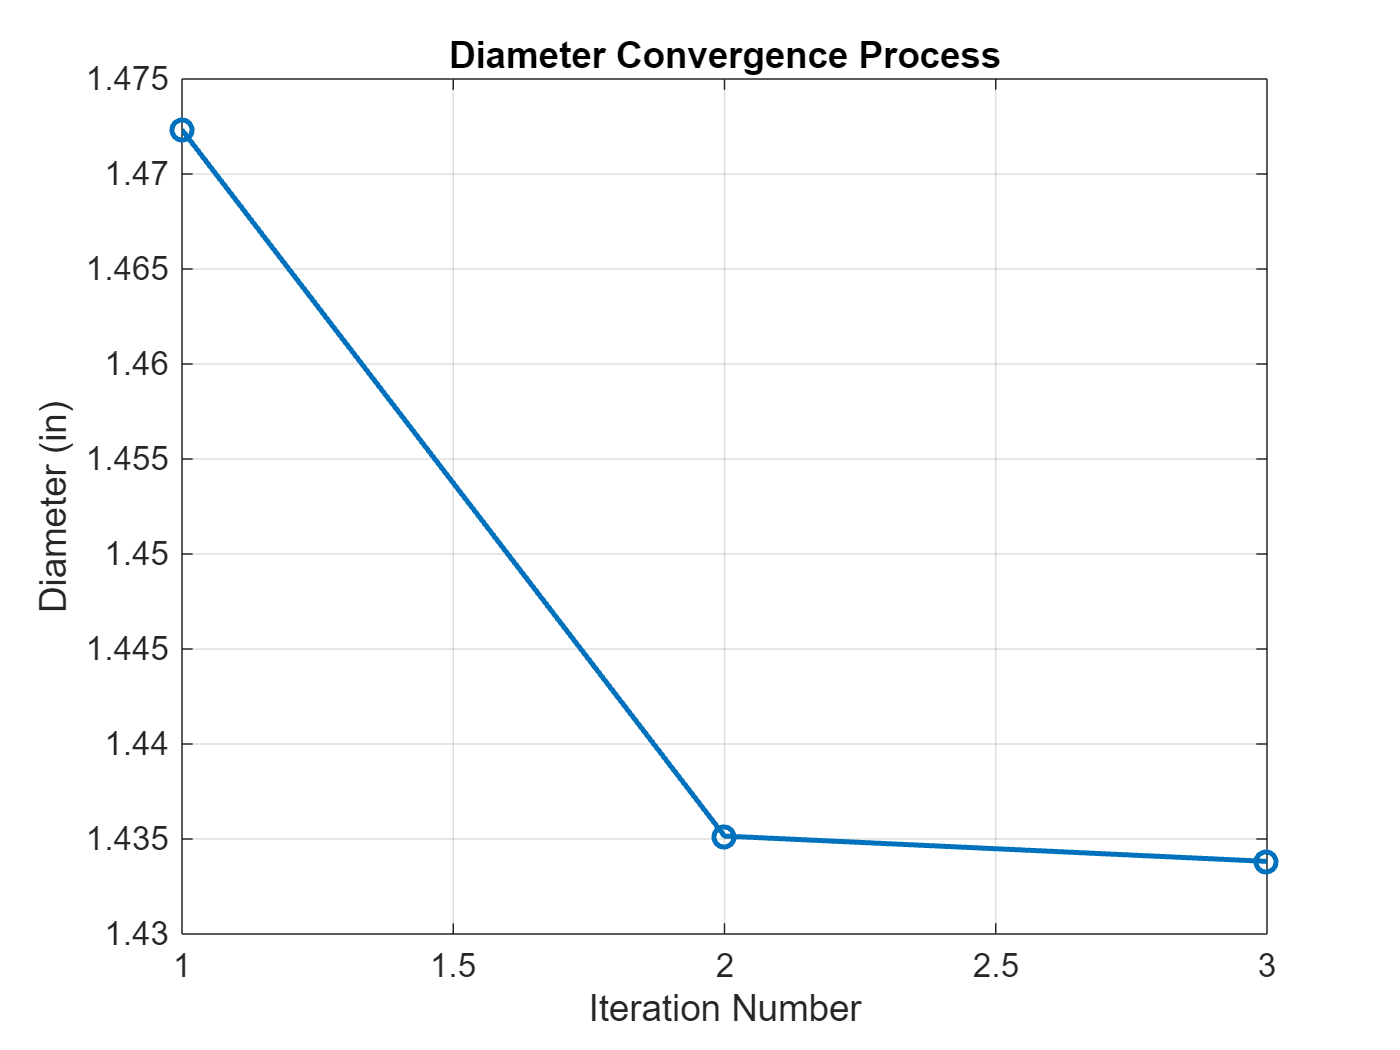

d_list = resize(d_list,[iter 1]);
figure(1);
plot(1:iter,d_list,'-o', 'LineWidth', 1.5);
xlabel('Iteration Number');
ylabel(sprintf('Diameter (%s)', length_unit));
title('Diameter Convergence Process');
grid on;